## 图形与数据可视化

### 绘制二维图形

要求：绘制函数曲线 $y=2x^2 +5x-6$, x范围[-10,10]。显示网格线，添加X轴和Y轴名称，显示标题，设置X轴范围[-12,12]，Y轴范围[-20,300]。

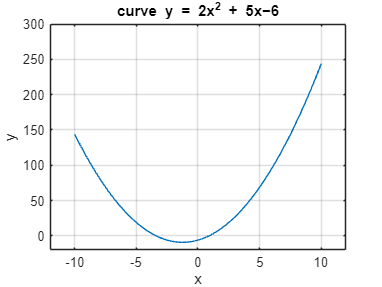

clear
close all
x = -10:0.1:10;
y = 2*x.^2+5*x-6;
plot(x,y);
grid on
xlabel("x")
ylabel("y")
title("curve y = 2x^2 + 5x−6")
axis([-12, 12, -20, 300])

### 绘制多重图形

要求：在同一窗口绘制两条曲线：y1=sin(3x)和y2=2cos(x)。y1要求用红色点划线表示，标记点为星号；y2用蓝色虚线表示，标记点为圆圈。添加y1和y2的图例，x轴刻度以π为增量显示。

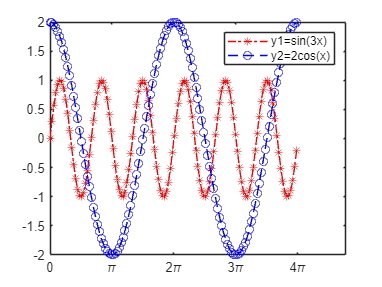

clear
close all
x = 0:0.1:4*pi;
y1 = sin(3*x);
y2 = 2*cos(x);
plot(x, y1, '-.*r', x, y2, '--ob');  
legend('y1=sin(3x)','y2=2cos(x)')  
xticks(0:pi:4*pi)
xticklabels({'0','\pi','2\pi','3\pi','4\pi'}) 

### 绘制子图

要求：在一个图形窗口中分别绘制正弦、余弦、正切和余切函数曲线。

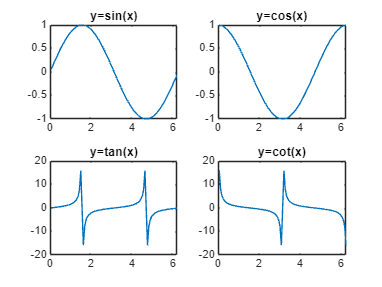

clear
close all
x = 0:pi/50:2*pi;
k = [1 26 51 76 101];  % 正切和余切函数的奇异点
x(k) = [];
subplot(2,2,1);
plot(x,sin(x));
title('y=sin(x)');
subplot(2,2,2);
plot(x,cos(x));
title('y=cos(x)');
subplot(2,2,3);
plot(x,tan(x));
title('y=tan(x)');
subplot(2,2,4);
plot(x,cot(x));
title('y=cot(x)');

### 绘制三维图形

要求：在一个图形窗口中绘制函数的三维线图、网格曲面图和表面图。$z=x^4 +{\left(y-0\ldotp 4\right)}^4 -\textrm{xy}$.

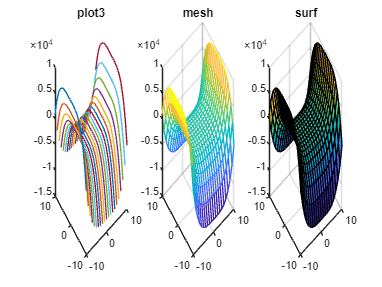

clear
close all
[x, y] = meshgrid(-10:1:10);
z = x.^4 - (y-0.4).^4 - x*y;
subplot(1,3,1);
plot3(x, y, z);         
title('plot3');
subplot(1,3,2);
mesh(x, y, z);
title('mesh');
subplot(1,3,3);
surf(x, y, z);
title('surf');

### 绘制数据分布图

要求：某公司本月发放工资如下（单位：元） 8200 12200 9000 6850 7800 8500 7500 4800 9200 7600 6250 10800 11500 8200 11000 12800 7800 7250 7500 8600 8200 6300 12000 6500 7800 5500 6600 7500 8200 9000 6800 8300 7800 8500 7500 4800 9100 6800 7600 15000 6500 8200 20000 9800 7800 18000 10500 5700 7500 8200 6000 6800 7800 5500 7900 5500 7500 7000 7100 5800, 计算平均工资，绘制直方图，并统计工资超过10000元的人数。

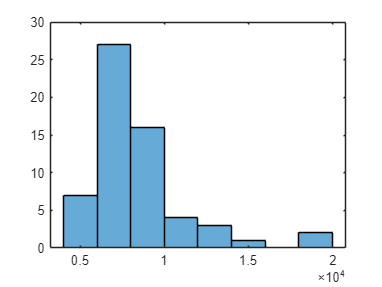

clear
close all
salary = [8200 12200 9000 6850 7800 8500 7500 4800 9200 7600 6250 10800 ...
          11500 8200 11000 12800 7800 8250 7500 8600 8200 6300 12000 ...
          6500 7800 5500 6600 7500 8200 9000 6800 8300 7800 8500 7500 4800 ...
          9100 6800 7600 15000 6500 8200 20000 9800 7800 18000 10500 5700 ...
          7500 8200 6000 6800 7800 5500 7900 5500 7500 7000 7100 5800];
average = mean(salary);
x = 4000:2000:20000;
histogram(salary, x);

num = length(find((salary>=10000)));
disp(average);

   8.3875e+03



disp(num);

    10



### 绘制离散数据图

要求：随机生成100×4的数组，绘制散点图：第一列为横坐标，第二列为纵坐标，(第三列×50)决定标记大小，(第四列×10)决定颜色，标记形状为实心菱形。

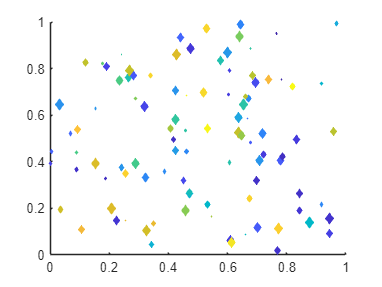

clear
close all
data = rand(100,4);
x = data(:,1);
y = data(:,2);
sz = 40 * data(:,3);
color = 10 * data(:,4);
scatter(x,y,sz, color, 'filled', 'd');

### 绘制矢量场图

要求：绘制二维和三维矢量图 $z=y^2 -x^2$.

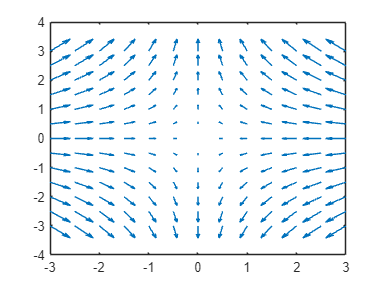

clear
close all
[x, y] = meshgrid(-3:0.5:3, -3:0.5:3);
z = y.^2 - x.^2;
[u, v] = gradient(z, 2, 2);
quiver(x, y, u, v);

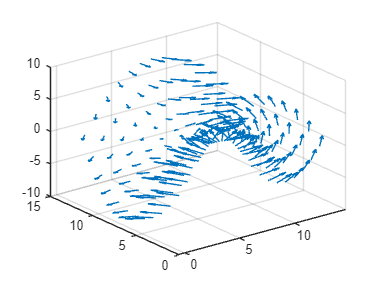

[u, v, w] = surfnorm(z);
quiver3(z, u, v, w);

### 体积可视化实践

要求：创建三维体积数据$V=x^2 +y^2 +z^2 -25$绘制垂直于X轴在-3、0、3处的切片平面，以及垂直于Z轴在-4、0处的切片平面。

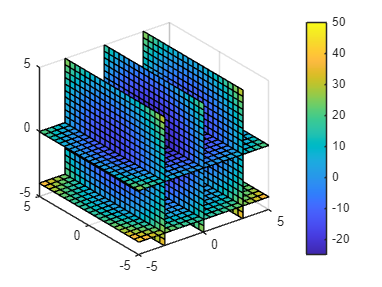

clear
close all
[x,y,z]=meshgrid(-5:0.5:5);
V = x.^2 + y.^2 + z.^2 - 25;
xslice = [-3 0 3];        
yslice = [];
zslice = ([-4 0]);
slice(x, y, z, V, xslice, yslice, zslice)   
cb = colorbar; 